# Exercise 5.1 - Spectrograms

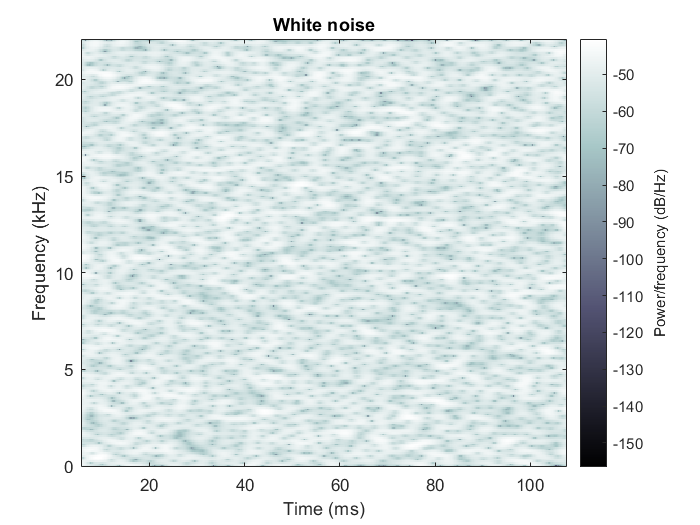

% Import audio files.
[whiteNoise, fs1] = audioread('audio\ruidoblanco.wav');
[whistle, fs2] = audioread('audio\whistle.wav');
[bee5th, fs3] = audioread('audio\bee5th.wav');

% Trim a fragment off of the white noise signal.
whiteNoiseFrag = whiteNoise(1 : 5000); 

% Play audio signals.
%sound(whiteNoiseFrag, fs1);
%sound(whistle, fs2);
sound(bee5th, fs3);

% Plot their spectrograms.
colormap bone;
spectrogram(whiteNoiseFrag, kaiser(512, 18), 500, 512, fs1, 'yaxis'), title('White noise');

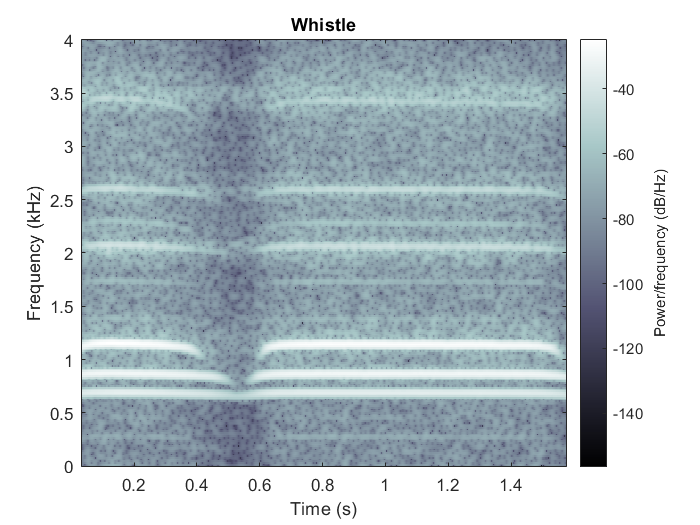

spectrogram(whistle, kaiser(512, 18), 500, 512, fs2, 'yaxis'), title('Whistle');

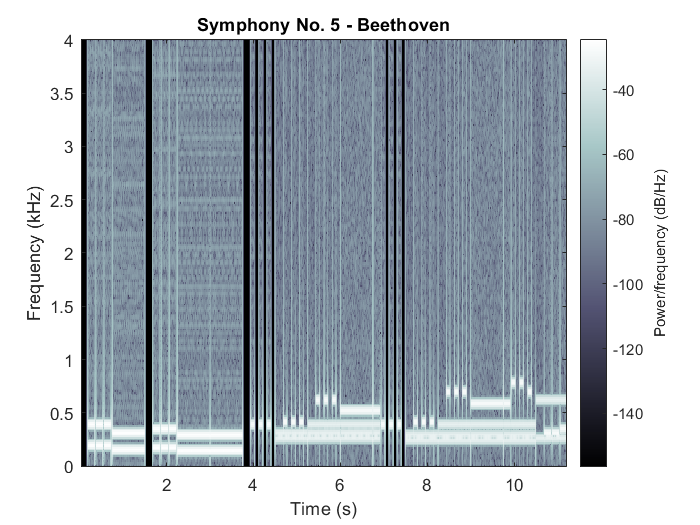

spectrogram(bee5th, kaiser(512, 18), 500, 512, fs3, 'yaxis'), title('Symphony No. 5 - Beethoven');